clear
load('C:\Users\Will\OneDrive\MyMatlab\metametric\naturePaper\CH11_Optims.mat')
load('C:\Users\Will\OneDrive\MyMatlab\metametric\SolutionOutputs\compareNature11CH_Max.mat')
Smax = SolutionArray;
Smax = Smax( [Smax.rf]>85);
load('C:\Users\Will\OneDrive\MyMatlab\metametric\SolutionOutputs\compareNature11CH_Min.mat')
Smin = SolutionArray;
Smin = Smin( [Smin.rf]>85);

myCCTs = unique([round([Smin.cct]), round([Smax.cct]) ]);
for i = 1:numel(myCCTs)
    SminTemp = Smin( round([Smin.cct]) == myCCTs(i) );
    [~, idxBestMin] = min([SminTemp.melOpicDER]);
    SminBest(i) = SminTemp(idxBestMin);

    SmaxTemp = Smax( round([Smax.cct]) == myCCTs(i) );
    [~,idxBestMax] = max([SmaxTemp.melOpicDER]);
    SmaxBest(i) = SmaxTemp(idxBestMax);
end

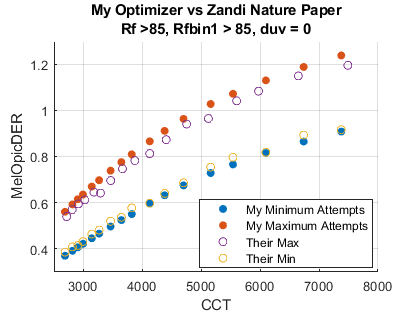

myFig=figure;
myFig.Units = 'normalized';
myMin = scatter([SminBest.cct],[SminBest.melOpicDER],'filled');
hold on
myMax = scatter([SmaxBest.cct], [SmaxBest.melOpicDER],'filled');

theirMin = scatter(A_min.CCT_Actual, A_min.MelanopicDER_250lx);
theirMax = scatter(A_max.CCT_Actual, A_max.MelanopicDER_250lx);
ylim([0.3, 1.3])
xlim([2500,8000])
% scatter([SminBest.cct], [SminBest.melOpicDER],'*');
% scatter([SmaxBest.cct], [SmaxBest.melOpicDER],'*');

legend([myMin,myMax,theirMax,theirMin],...
    {'My Minimum Attempts', 'My Maximum Attempts', 'Their Max', 'Their Min'},...
    'location','best')
xlabel('CCT')
ylabel('MelOpicDER')
grid on
title("My Optimizer vs Zandi Nature Paper" + newline() + "Rf >85, Rfbin1 > 85, duv = 0")
exportgraphics(gcf,'MeVsZandiNature.png')

% [A_min.CCT_Actual,A_min.MelanopicDER_250lx,A_min.Rf_Actual]

TableMin = struct2table(SminBest);
TableMin.wl = [];
TableMin.sref = [];
TableMin.stest =[];
TableMin.stest0 = [];
TableMin(:,end+1) = TableMin(:,1);
TableMin(:,1) = [];


TableMax = struct2table(SmaxBest);
TableMax.wl = [];
TableMax.sref = [];
TableMax.stest =[];
TableMax.stest0 = [];
TableMax(:,end+1) = TableMax(:,1);
TableMax(:,1) = [];

wlVars = cellstr(string(380:1:780));

% TableMaxSPD = splitvars(TableMax, 'Var23', 'NewVariableNames',wlVars)

spdMins = cell2mat(table2cell(TableMin(:,end)));
spdMins = reshape(spdMins, [],401);
T = table(spdMins);

TableMin(:,end) = []

TableMin = 17×21 table
              t2XYZ                      t2xy                     t10XYZ                    t10xy                     r2XYZ                         r10XYZ               cct          duv        rf      rg         hsBins           csBins           rfBins            gref             gtest        sOpicDER    mOpicDER    lOpicDER    melOpicDER    rOpicDER     ELR2 
    __________________________    __________________    __________________________    __________________    __________________________    __________________________

TableMin = [TableMin, splitvars(T, 'spdMins','NewVariableNames',wlVars)]

TableMin = 17×422 table
              t2XYZ                      t2xy                     t10XYZ                    t10xy                     r2XYZ                         r10XYZ               cct          duv        rf      rg         hsBins           csBins           rfBins            gref             gtest        sOpicDER    mOpicDER    lOpicDER    melOpicDER    rOpicDER     ELR2        380           381           382           383           384           385           386           387           <s



spdMax = cell2mat(table2cell(TableMax(:,end)));
spdMax = reshape(spdMax, [],401);
T = table(spdMax);

TableMax(:,end) = []

TableMax = 17×21 table
              t2XYZ                      t2xy                     t10XYZ                    t10xy                     r2XYZ                         r10XYZ               cct          duv        rf      rg         hsBins           csBins           rfBins            gref             gtest        sOpicDER    mOpicDER    lOpicDER    melOpicDER    rOpicDER     ELR2 
    __________________________    __________________    __________________________    __________________    __________________________    __________________________

TableMax = [TableMax, splitvars(T, 'spdMax','NewVariableNames',wlVars)]

TableMax = 17×422 table
              t2XYZ                      t2xy                     t10XYZ                    t10xy                     r2XYZ                         r10XYZ               cct          duv        rf      rg         hsBins           csBins           rfBins            gref             gtest        sOpicDER    mOpicDER    lOpicDER    melOpicDER    rOpicDER     ELR2        380           381           382           383           384           385           386           387          

writetable(TableMin, 'metametricMin.csv')
writetable(TableMax, 'metametricMax.csv')


fig = uifigure();
uit = uitable('Parent',fig)

uit =   Table with properties:

                Data: []
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [20 20 300 300]
               Units: 'pixels'

  Show all properties


t = TableMax;
% t2 = t.t2XYZ;
t2 = splitvars(t(:,1), 't2XYZ', 'NewVariableNames', {'t2X','t2Y','t2Z'})

t2 = 17×3 table
     t2X       t2Y       t2Z  
    ______    ______    ______

     105.2    93.767    29.265
    103.27    93.535    32.251
    101.97    93.337    34.395
    100.88    93.218    36.491
    99.134    92.936    39.981
    97.867    92.734    42.879
    96.113    92.406    47.316
    94.682    92.096    51.395
    93.518    91.838    55.222
    91.817     91.39    61.589
    90.668    91.037    66.582
    89.493    90.631    72.588
    88.243    90.138    80.567
    87.501    89.801    86.602
    86.703    89.354    94.635
    86.083    88.904    102.73


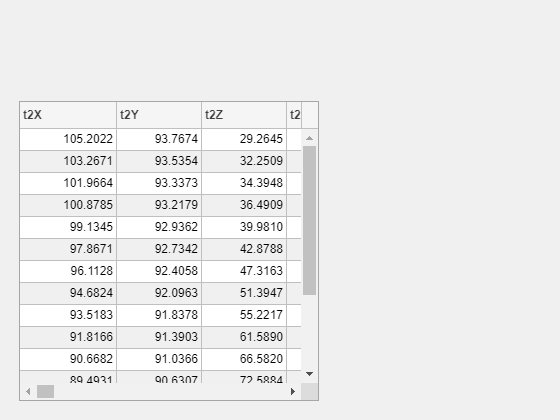

t = [t2,t(:,2:end)];
uit.Data = t;


load patients
Personal_Data = table(Gender,Age);
BMI_Data = table(Height,Weight);
BloodPressure = table(Systolic,Diastolic);
T1 = table(LastName,Personal_Data,BMI_Data,BloodPressure);
head(T1,3)

ans = 3×4 table
      LastName        Personal_Data          BMI_Data            BloodPressure    
                      Gender      Age    Height    Weight    Systolic    Diastolic
    ____________    _________________    ________________    _____________________

    {'Smith'   }    {'Male'  }    38       71       176        124          93    
    {'Johnson' }    {'Male'  }    43       69       163        109          77    
    {'Williams'}    {'Female'}    38       64       131        125          83    


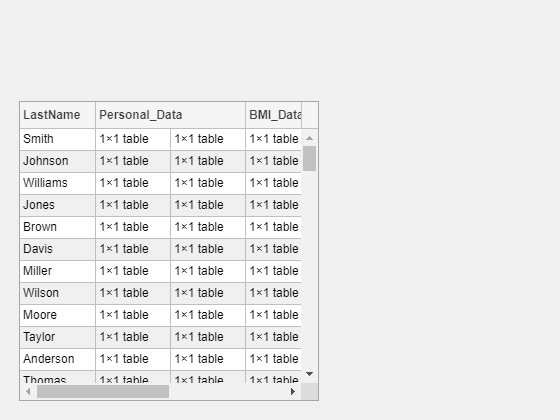


fig = uifigure();
uit = uitable('Parent',fig);
uit.Data = T1;